This is a summary of key findings and changes during model development, in

roughly chronological order.

- Some basic operations were done in for loops rather than as vectors.  I made the changes, speeding up the code by 10x or more.  This will mean less waiting during testing.

- The GUI is nice, but slow compare to just running code.  I made a simple script to bypass the GUI, with the intent or restoring it later.

- Side note: building a "mex" executable could be a big speed (and possibly memory) win if simulations become large and slow.

## Random walk bias

I noticed that the random walk was either 1 unit up or down, when it seems that a continuous distribution might make more sense.  The first paper I found (Visser 1997) points out a common error which leads to biased migration of particles toward areas of low diffusion.  We have that problem!  Running with a drop in diffusivity by a factor of 4 at 50 meters, this uneven distribution is obtained after 4 hours:

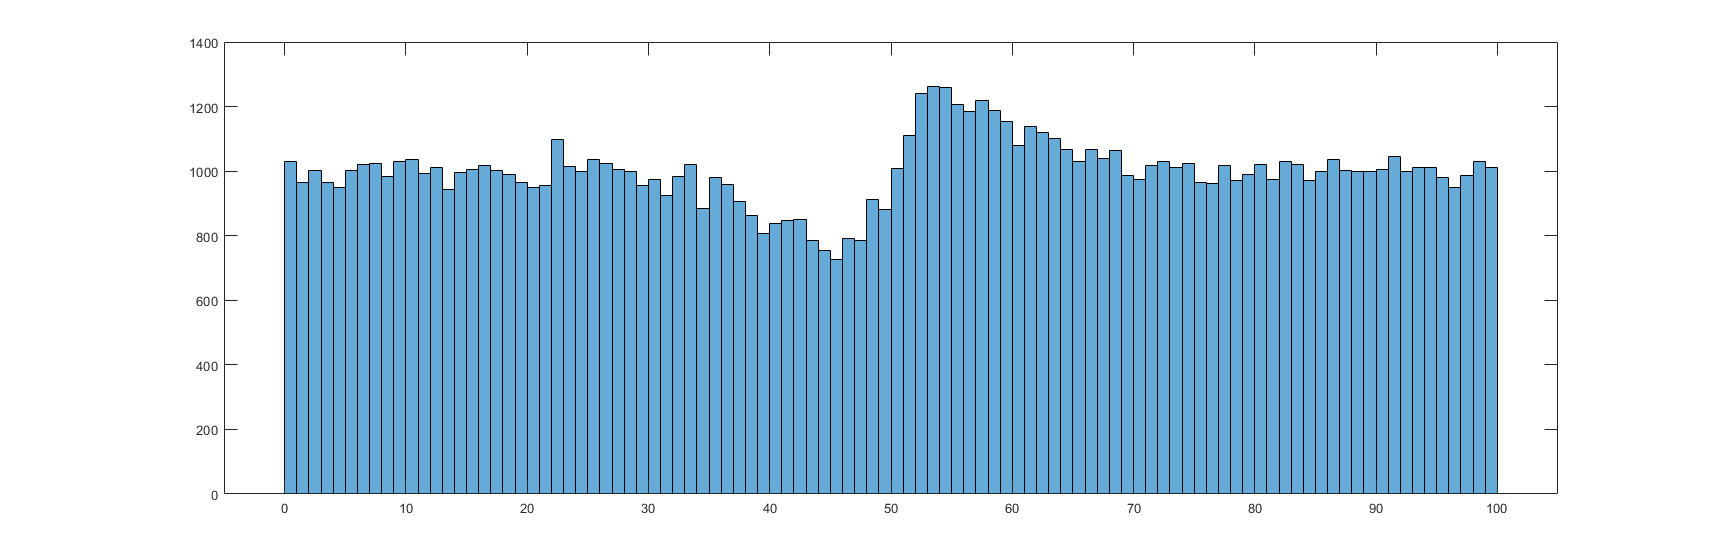

openfig('Biased_Diffusion.fig');

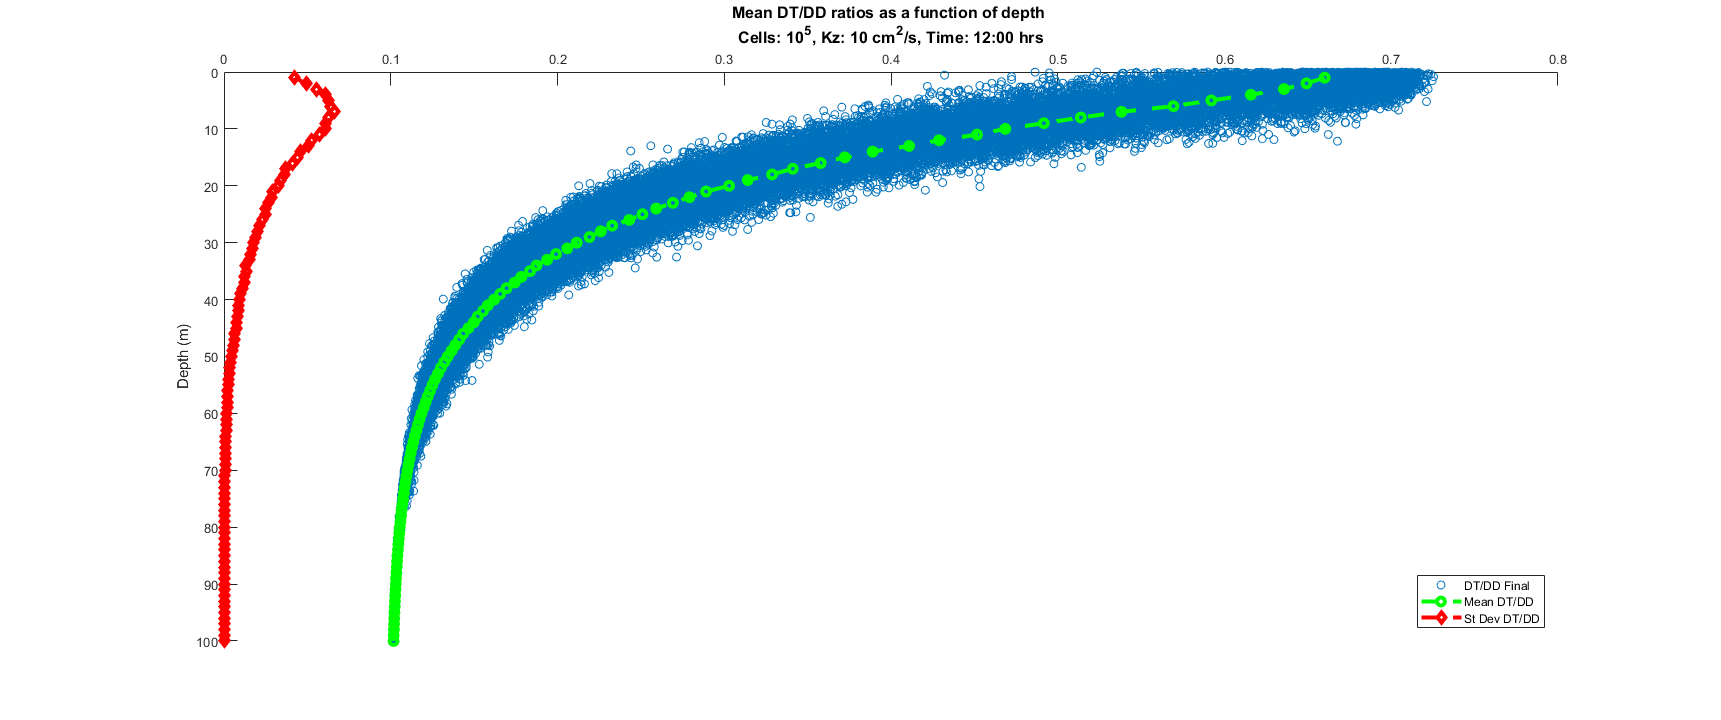

openfig('Biased_DTDD.fig');

The function in the original version uses the code 

`sqrt(2*dt*Kz)`

Representing a step size of

 $\pm \sqrt{2K\delta t}$  where the sign is chosen randomly.

Visser (1997) equation 3 shows

$R\sqrt{\frac{2}{r}K\delta t}$  where R is random and r is the standard deviation of R.

however Visser points out that this leads to a bias when K is not constant, recommending (equation 6)

$\mathrm{K'}\left(z\right)\delta t+R\sqrt{\left\lbrace \frac{2}{r}K\left\lbrack z+\frac{1}{2}\mathrm{K'}\left(z\right)\delta t\right\rbrack \delta t\right\rbrace }$ where $\mathrm{K'}=\frac{\delta K}{\delta z}$

BUT the square brackets are meant to imply that K is a function of the contents, not normal mathematical grouping!

Examples in the paper use a uniform distribution from -1 to 1 for R, not a normal distribution, so I will do the same.  The standard deviation is then $\sqrt{\frac{1}{3}}$.

The figures above are repeated below with the new approach.  Not that particles are no longer "pumped" from high to low diffusion areas.  Run time increases from 2.31 to 3.12 seconds for n=5, due to the extra interpolations.  **Note** that the effective diffusion rate is lower since step sizes range between 0 and 0.4558, as opposed to being fixed at 0.3464 in the original code.

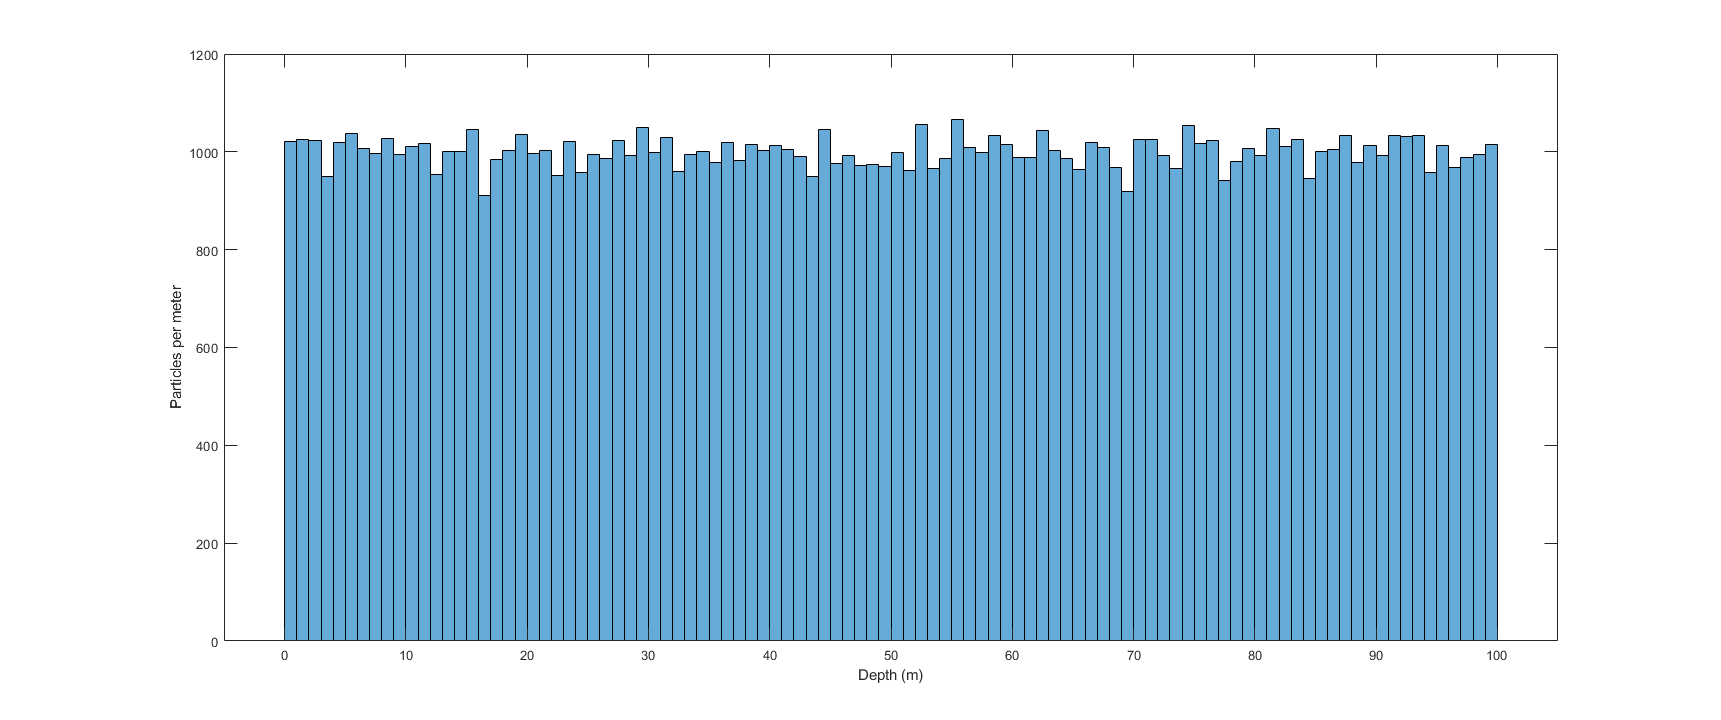

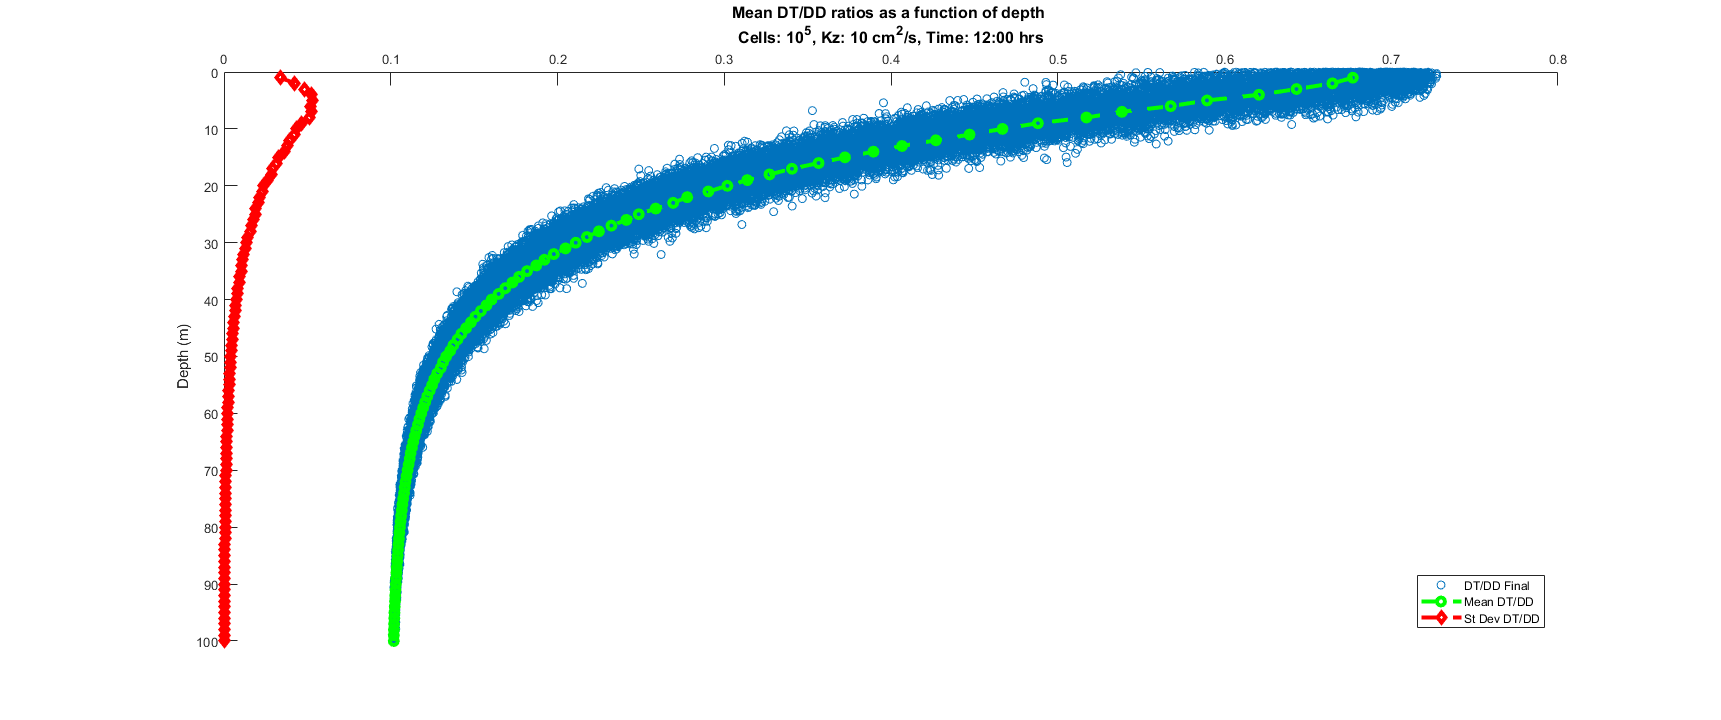

openfig('Diffusion_VisserEq6.fig'); openfig('DTDD_VisserEq6.fig');

## Adding the Thermocline

## References

North, E. W., Hood, R. R., Chao, S. Y. & Sanford, L. P. Using a random displacement model to simulate turbulent particle motion in a baroclinic frontal zone: A new implementation scheme and model performance tests. *J. Mar. Syst.* **60,** 365–380 (2006).

Visser, A. Using random walk models to simulate the vertical distribution of particles in a turbulent water column. *Mar. Ecol. Prog. Ser.* **158,** 275–281 (1997).